## Figure 3 

clear all; close all; clc;

%add the source data
addpath 'path\to\data_source';
addpath 'path\to\INTHIS\DataAnalysis';

%load 
load S.mat;

%load all meshes
%select 
%FBG Skin DOMAIN
load FBG_x.csv;
load FBG_y.csv;
load FBG_z.csv;

%FBG Skin DOMAIN
load xi.csv;
load yi.csv;
load zi.csv;

%load NN structure

%get sensorspositions
load sx.csv;
load sy.csv;
load sz.csv;

%get neuronspositions
load xc.csv
load yc.csv;
load zc.csv;
Tri = delaunay(xc,yc);

%get motorpositions
load xm.csv
load ym.csv;
load zm.csv;

%read stl of sensors line
importstl=stlread("path_fbg.stl");

%load deltas
load deltax.mat
load deltay.mat
load deltaz.mat

%compute lines
linex=-importstl.Points(:,1)+deltax;
liney=importstl.Points(:,3)+deltay;
linez=importstl.Points(:,2)+deltaz;

load Wh.csv
load Wh2.csv

## subfigures

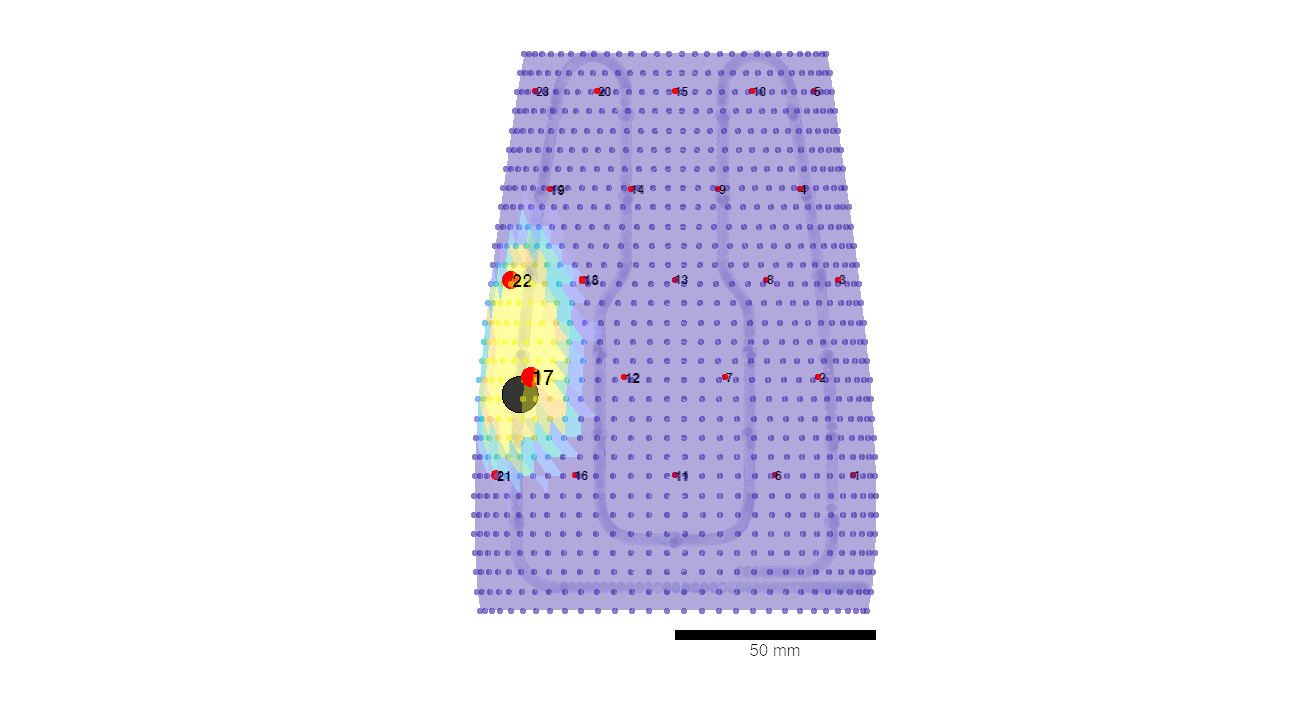

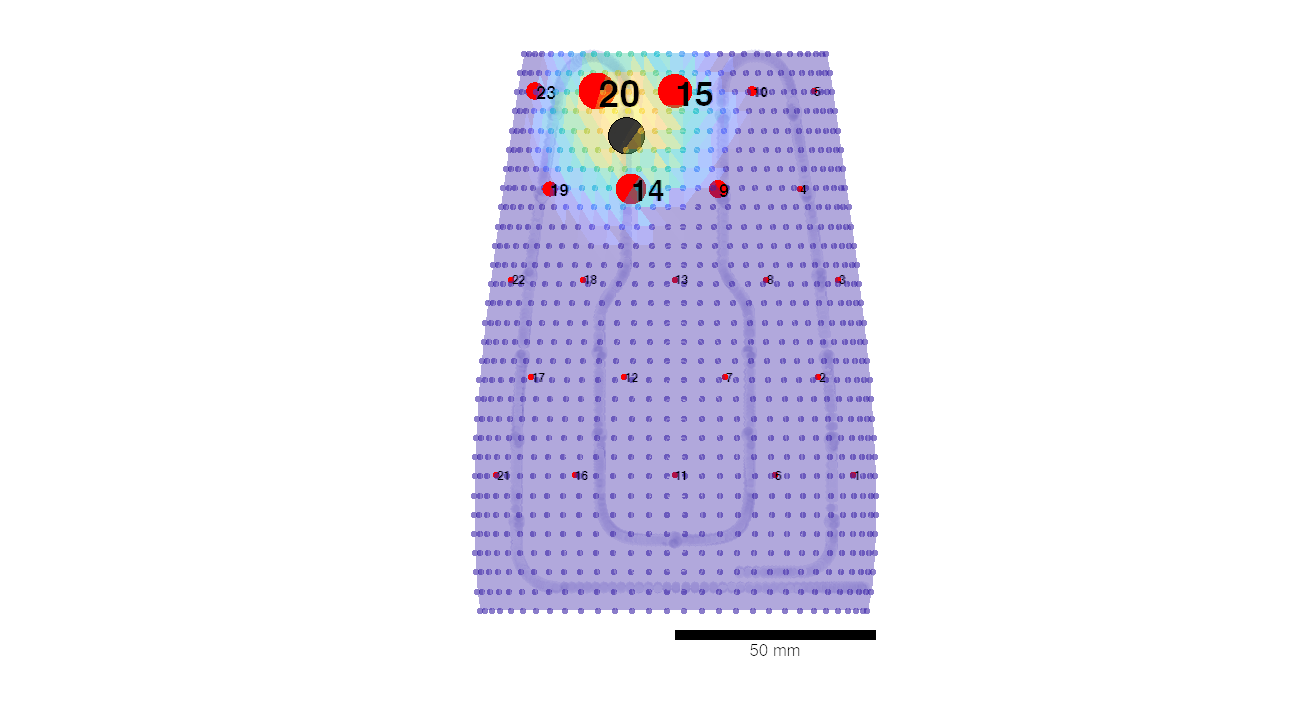

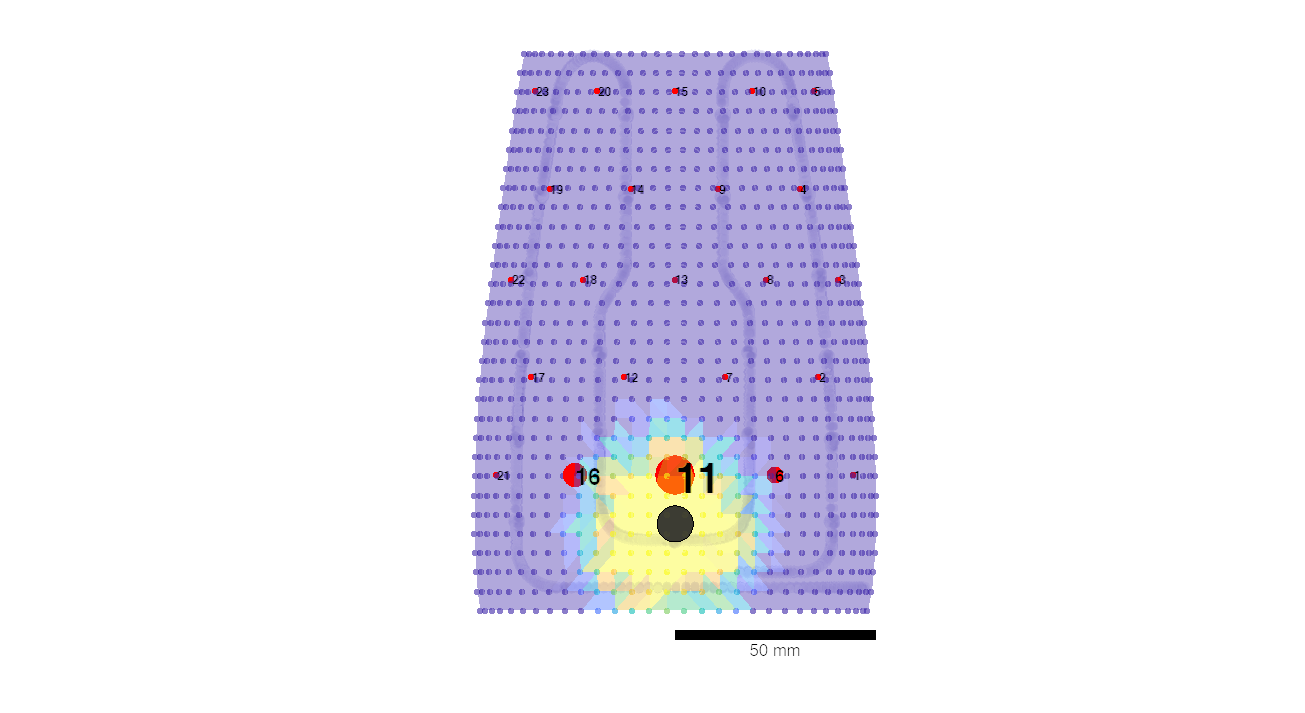

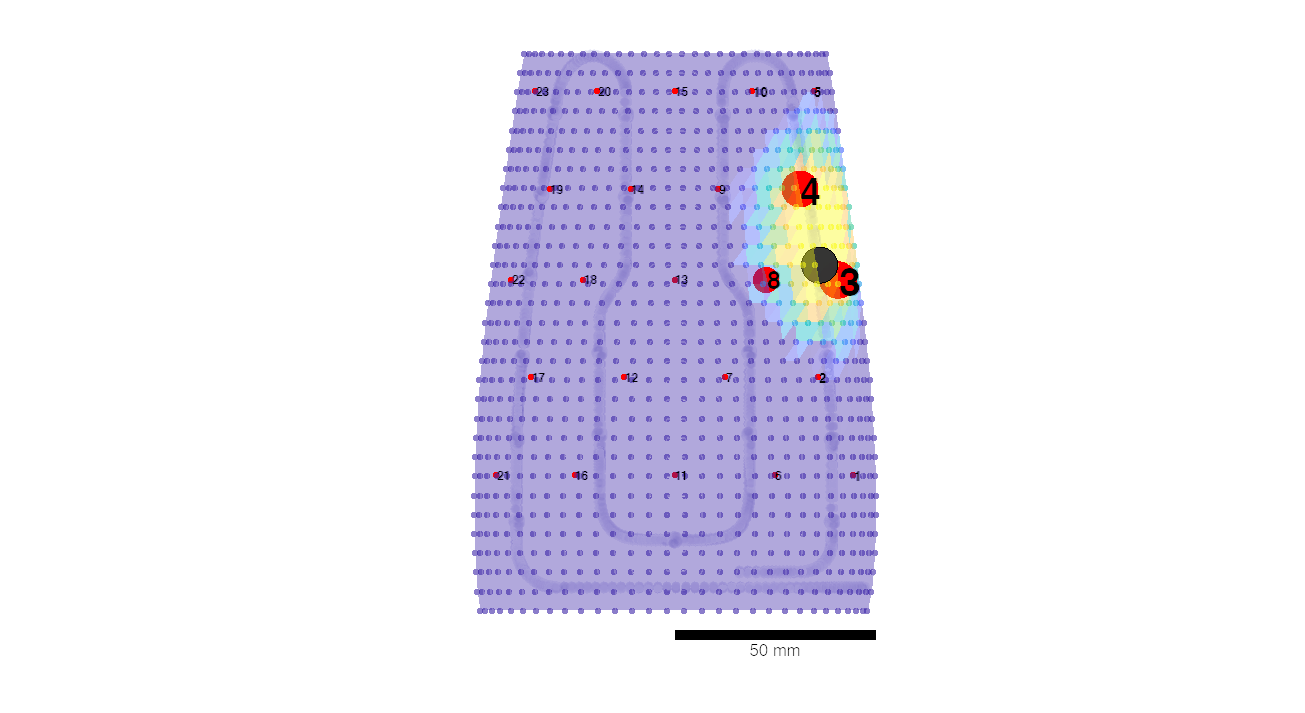

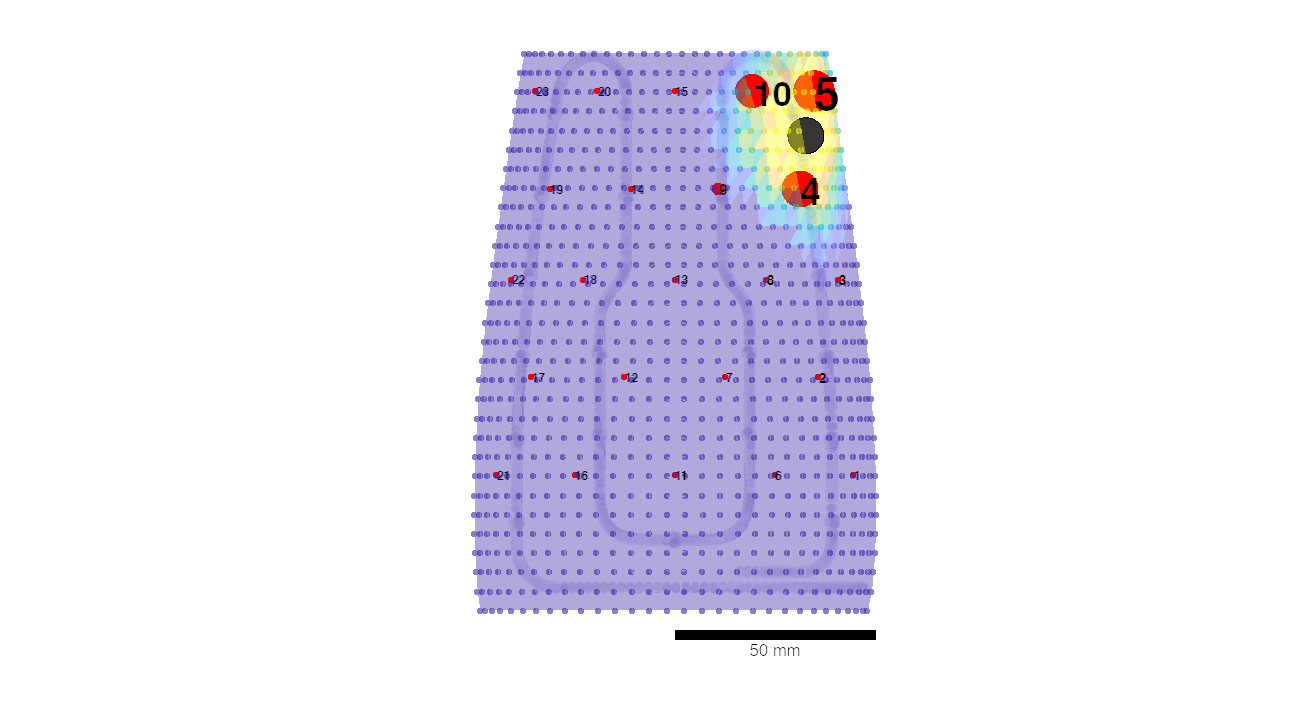

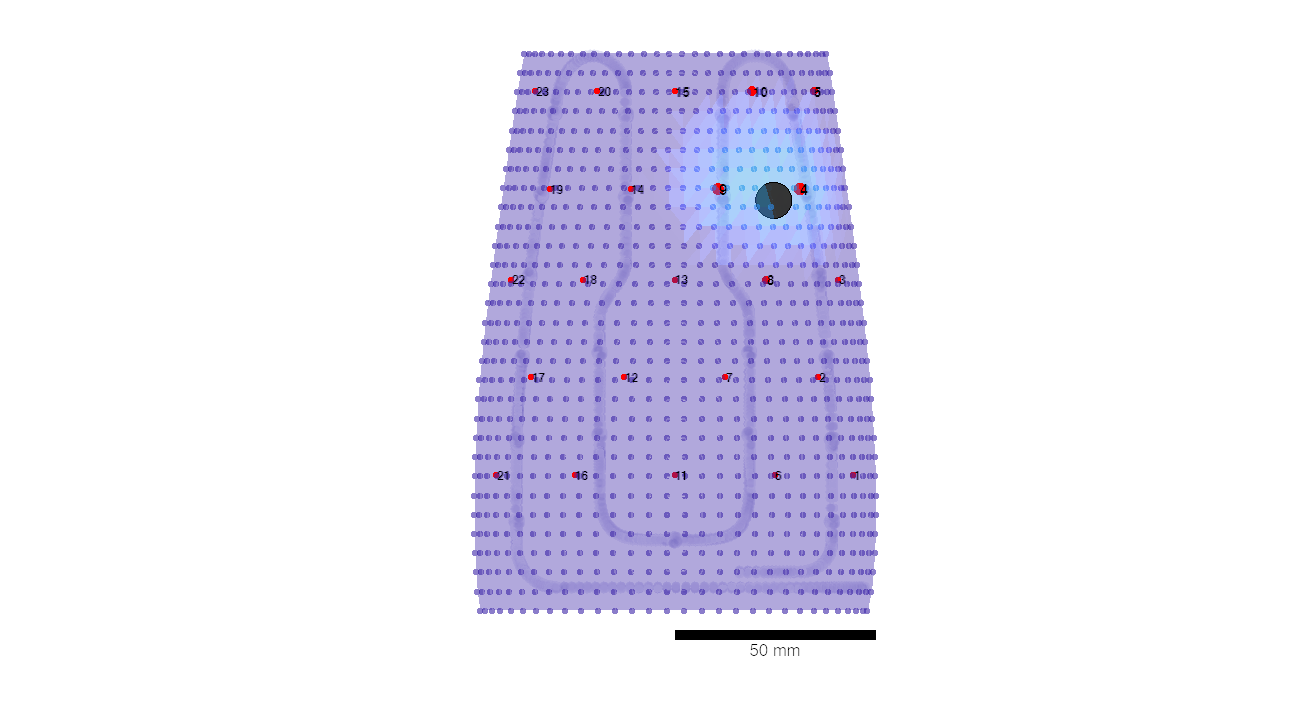

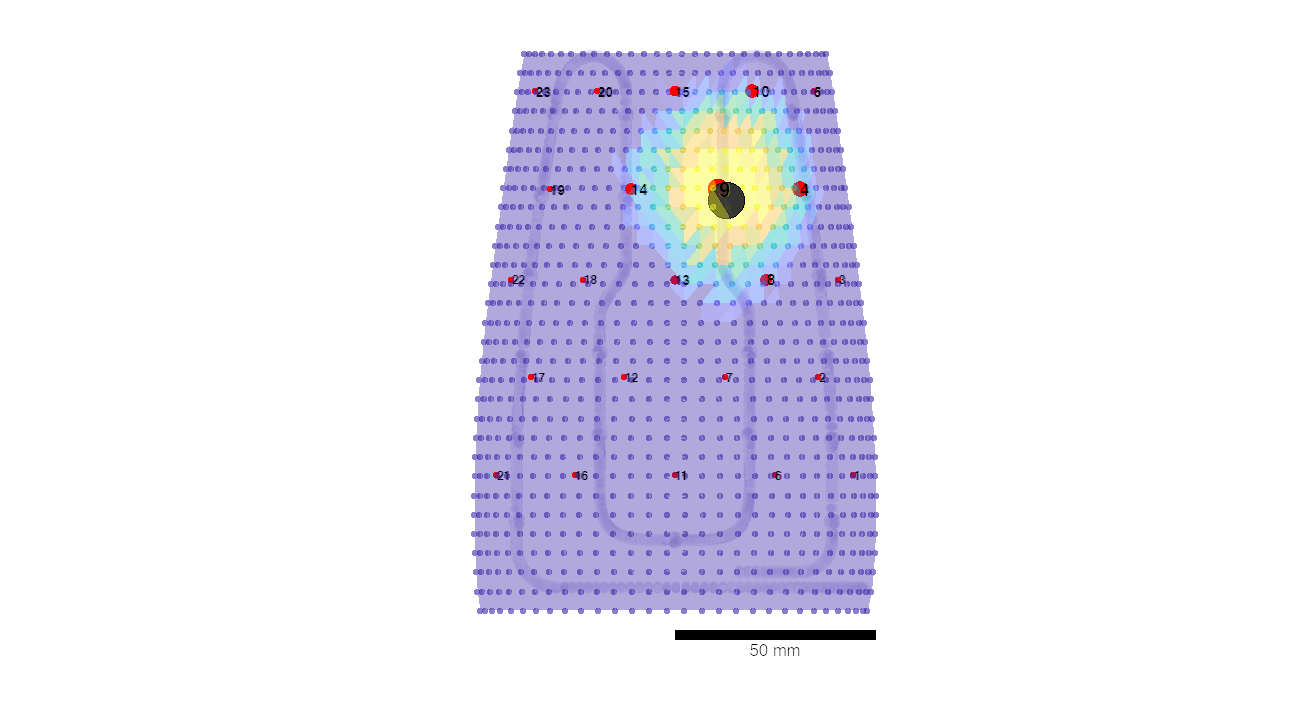

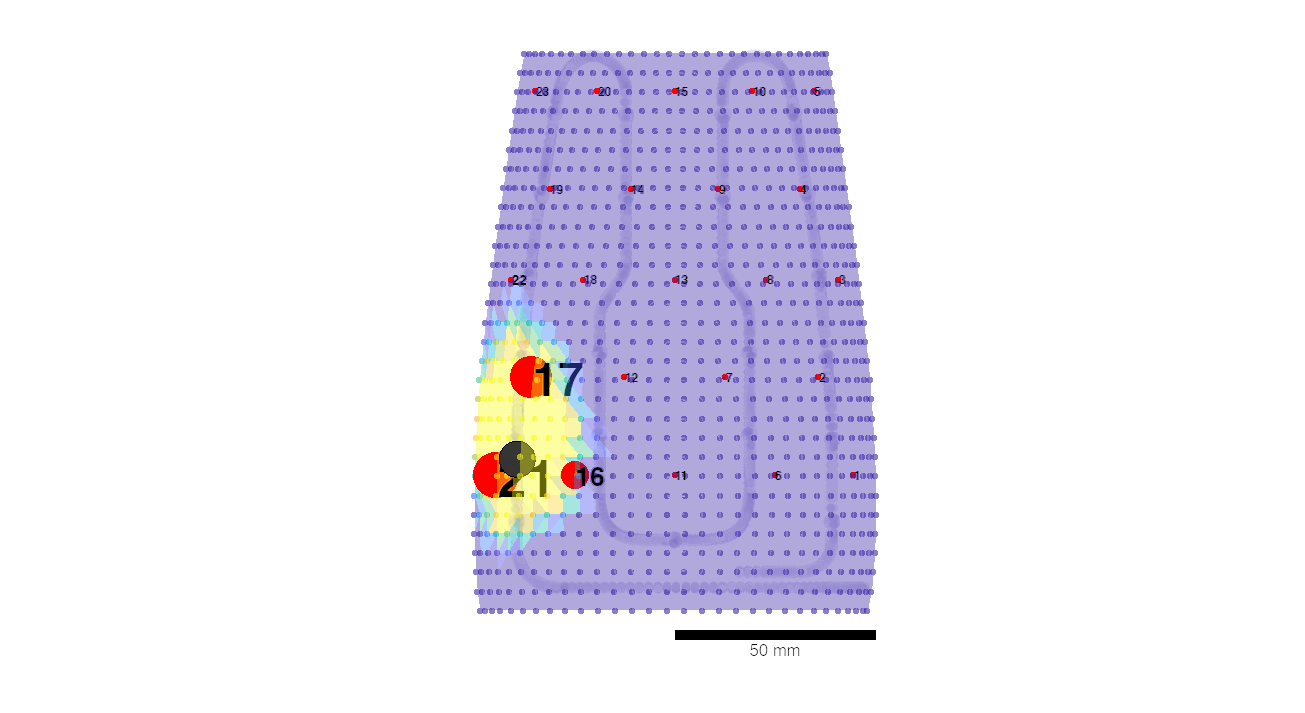

%for subject number 6
Sn="S6";

%select a set of representative trials
trials=[9 15 16 19 23 33 61 66];

%for each of them

for t=1:length(trials)

        %get the trial
        Tn=sprintf("T%d",trials(t));
        
        %get the spike data
        fbgs=S.(Sn).(Tn).FBGs;
        neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1; %from labview/arduino to matlab!
        motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
        roi=S.(Sn).(Tn).ROI;
        ind=S.(Sn).(Tn).Ind;
        
        %threshold the fbgs
        fbgs(:,2:end)=fbgs(:,2:end)-fbgs(1,2:end);
        
        %compute the firing rates
        neuronsFR=computeFR(neurons,900);
        motorsFR=computeFR(motors,23);
                
        %create figure
        sub=figure('Units', 'Normalized', 'OuterPosition', [0.05 0.05 0.95 0.95]);
        hold on; view(0,90);
        colormap(slanCM('parula')); clim([0 130]);
        
        %visual data in the FBG domain
        %title(sprintf('%s %s',Sn,Tn));
        hold on; 


        %neurons
        scatter3(xc,yc,zc,15,neuronsFR,'filled','markerFaceAlpha',0.6); 
        trisurf(Tri, xc, yc, zc,neuronsFR,'EdgeAlpha',0,'FaceAlpha',0.4);
        scatter3(linex,liney,linez,30,"MarkerFaceColor",[0.0504	0.02980	0.5280],"MarkerFaceAlpha",0.01,"MarkerEdgeColor","none");
        
        %motors
        scatter3(xm,ym,zm,motorsFR*2.5+15,'or','filled','AlphaData',0.8);
        for i=1:length(xm)
            text(xm(i),ym(i),zm(i)+6,sprintf('%d',i),'Color','k','FontSize',ceil(motorsFR(i)/12)+7,'FontWeight','bold');
        end
        colormap(slanCM('parula')); clim([0 130]);
        
         %barscale
        if 1 
            xstart=0;
            ybar=-2;
            barlength=50;
            plot([xstart xstart+barlength],[ybar ybar],'k','LineWidth',6);
            text((xstart+xstart+barlength) / 2, ybar-1, ...
                [num2str(barlength), ' mm'], 'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'top', 'FontSize', 10);
        end

        %the real position
        %scatter3(REALposition(1),REALposition(2),REALposition(3),30,'filled','g','MarkerEdgeColor','none','MarkerFaceAlpha',1,'MarkerFaceColor','b');
        plotCoin(4.5,[xi(ind),yi(ind),zi(ind)],0.5,100,[0.2 0.2 0.2]);

        %settings
        view(0,90);
        axis equal;
        grid on;
        hold off;
        recolorfig;
        axis off;

        %export
        saveas(sub,fullfile("subfigures",sprintf("sub_%s_%s.fig",Sn,Tn)));
        exportgraphics(sub, fullfile("subfigures",sprintf("sub_%s_%s.png",Sn,Tn)), 'ContentType', 'image','Resolution',300);
        exportgraphics(sub, fullfile("subfigures",sprintf("sub_%s_%s.pdf",Sn,Tn)), 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);
end